%{
Name: Wind Turbine Power Output 
Author: Evan Scheuritzel
Version: 1.0
Purpose: analyaze a theoretical wind turbines power variance
Input: none
Output: plots containg possible power output and wind speeds
%}

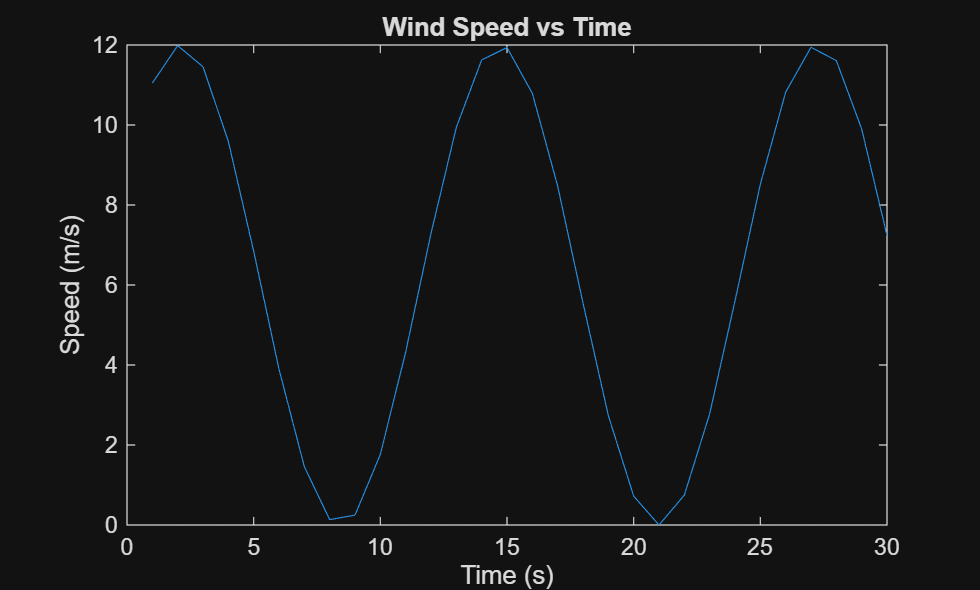

clear
t = 1:30;
%wind in m/s
windS = sin(1:.5:15.5)*6+6;
% Calculate the power output based on wind speed using a simple model
powerOutput = 0.5 * (windS.^3);
plot(t,windS)
xlabel('Time (s)');
ylabel('Speed (m/s)');
title('Wind Speed vs Time');

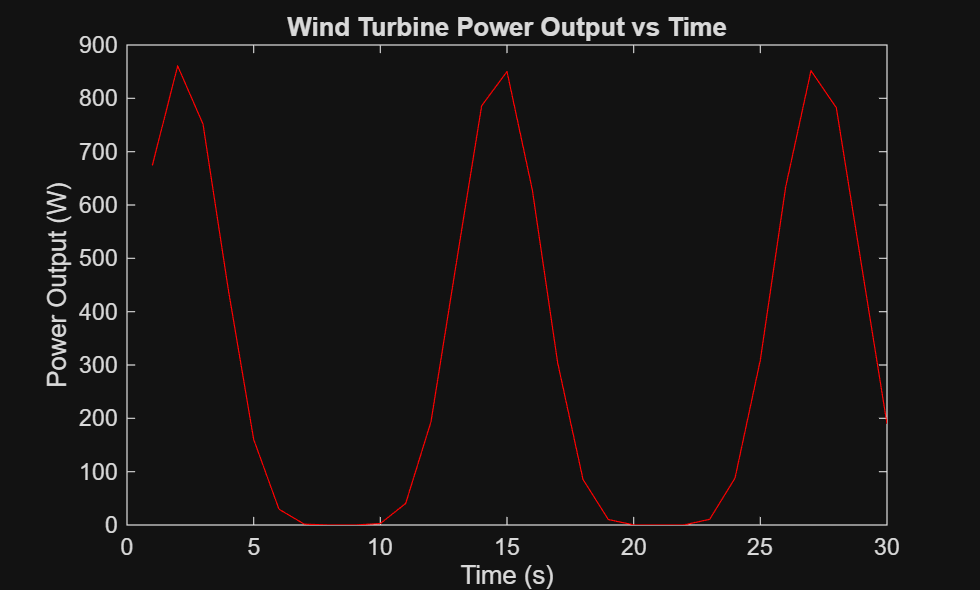


plot(t,powerOutput,'red')
xlabel('Time (s)');
ylabel('Power Output (W)');
title('Wind Turbine Power Output vs Time');

% Wind power would be rely on the whims of the air speed, meaning it can be
% inconsitient. This would add unnecesary strain to the power grid, would
% need batterys to mitigate and protect from sudden highs and sudden lows.